## **Loading in the Data**

The data.mat file has all of the networks (Face-to-Face and Co-Presence).

load('-mat', 'data.mat');

## **Calculate number of edges**

Each network is an adjacency matrix that looks like this:

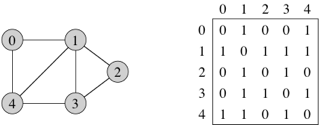

Our first task is to calculate the number of edges in each network. To do this, we add up all of the 1's in the adjacency matrix and divide by 2. The reason we divide by 2 is because each edge is double counted. We use the sum(A, 'all') command on MATLAB to calculate the sum of A where A is a matrix and 'all' to specify the command to add all of the values in the matrix. We can also just calculate the number of 1's in the upper or lower triangle of the matrix.

A_InVS13_SumOfEdges = sum(A_InVS13, 'all')/2;
A_InVS15_SumOfEdges = sum(A_InVS15, 'all')/2;
A_LH10_SumOfEdges = sum(A_LH10, 'all')/2;
A_LyonSchool_SumOfEdges = sum(A_LyonSchool, 'all')/2;
A_pres_InVS13_SumOfEdges = sum(A_pres_InVS13, 'all')/2;
A_pres_InVS15_SumOfEdges = sum(A_pres_InVS15, 'all')/2;
A_pres_LH10_SumOfEdges = sum(A_pres_LH10, 'all')/2;
A_pres_LyonSchool_SumOfEdges = sum(A_pres_LyonSchool, 'all')/2;
A_pres_SFHH_SumOfEdges = sum(A_pres_SFHH, 'all')/2;
A_pres_Thiers13_SumOfEdges = sum(A_pres_Thiers13, 'all')/2;
A_SFHH_SumOfEdges = sum(A_SFHH, 'all')/2;
A_Thiers13_SumOfEdges = sum(A_Thiers13, 'all')/2;

disp(A_InVS13_SumOfEdges);

   755



Above displays the number of edges in the A_InVS13 neptwork.

## **Calculating the Density of each adjacency list**

In order to do this, we must use this equation to calculate the density.


$$\begin{array}{l}
\\
\textrm{density}=\frac{\left(2m\right)}{n\left(n-1\right)}
\end{array}$$


A_InVS13_Density = (2*A_InVS13_SumOfEdges)/(length(A_InVS13)*(length(A_InVS13) - 1));
A_InVS15_Density = (2*A_InVS15_SumOfEdges)/(length(A_InVS15)*(length(A_InVS15) - 1));
A_LH10_Density = (2*A_LH10_SumOfEdges)/(length(A_LH10)*(length(A_LH10) - 1));
A_LyonSchool_Density = (2*A_LyonSchool_SumOfEdges)/(length(A_LyonSchool)*(length(A_LyonSchool) - 1));
A_pres_InVS13_Density = (2*A_pres_InVS13_SumOfEdges)/(length(A_pres_InVS13)*(length(A_pres_InVS13) - 1));
A_pres_InVS15_Density = (2*A_pres_InVS15_SumOfEdges)/(length(A_pres_InVS15)*(length(A_pres_InVS15) - 1));
A_pres_LH10_Density = (2*A_pres_LH10_SumOfEdges)/(length(A_pres_LH10)*(length(A_pres_LH10) - 1));
A_pres_LyonSchool_Density = (2*A_pres_LyonSchool_SumOfEdges)/(length(A_pres_LyonSchool)*(length(A_pres_LyonSchool) - 1));
A_pres_SFHH_Density = (2*A_pres_SFHH_SumOfEdges)/(length(A_pres_SFHH)*(length(A_pres_SFHH) - 1));
A_pres_Thiers13_Density = (2*A_pres_Thiers13_SumOfEdges)/(length(A_pres_Thiers13)*(length(A_pres_Thiers13) - 1));
A_SFHH_Density = (2*A_SFHH_SumOfEdges)/(length(A_SFHH)*(length(A_SFHH) - 1));
A_Thiers13_Density = (2*A_Thiers13_SumOfEdges)/(length(A_Thiers13)*(length(A_Thiers13) - 1));

## **Calculating Degree Distribution**

In order to calculate the degree distribution for each node/vertex in a vertex we must add up all of the 1's in each row. To do this we create a new variable and assign that variable to the sum of all 1's in each column in the database provided in the sum function.

A_InVS13_DegreeDistribution = sum(A_InVS13, 1);
A_InVS15_DegreeDistribution = sum(A_InVS15, 1);
A_LH10_DegreeDistribution = sum(A_LH10, 1);
A_LyonSchool_DegreeDistribution = sum(A_LyonSchool, 1);
A_pres_InVS13_DegreeDistribution = sum(A_pres_InVS13, 1);
A_pres_InVS15_DegreeDistribution = sum(A_pres_InVS15, 1);
A_pres_LH10_DegreeDistribution = sum(A_pres_LH10, 1);
A_pres_LyonSchool_DegreeDistribution = sum(A_pres_LyonSchool, 1);
A_pres_SFHH_DegreeDistribution = sum(A_pres_SFHH, 1);
A_pres_Thiers13_DegreeDistribution = sum(A_pres_Thiers13, 1);
A_SFHH_DegreeDistribution = sum(A_SFHH, 1);
A_Thiers13_DegreeDistribution = sum(A_Thiers13, 1);

## **Plotting Degree Distribution**

In order to compare the Face-to-Face networks and the Co-Presence networks we need to run histogram commands to visualize the data.

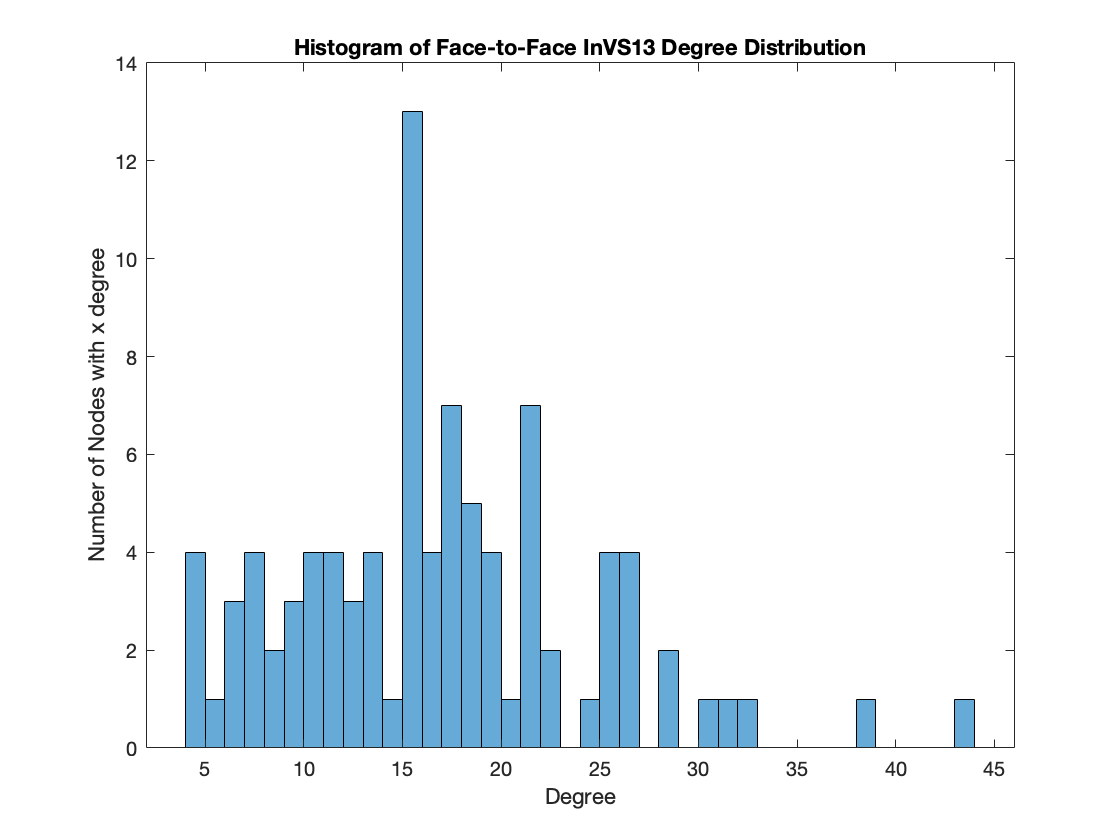

A_InVS13_DegreeDistributionHistogram = histogram(A_InVS13_DegreeDistribution);
A_InVS13_DegreeDistributionHistogram.BinWidth = 1;
xlabel('Degree');
ylabel('Number of Nodes with x degree');
title('Histogram of Face-to-Face InVS13 Degree Distribution');

disp(mean(A_InVS13_DegreeDistribution) + " " + std(A_InVS13_DegreeDistribution) + " " + var(A_InVS13_DegreeDistribution));

16.413 7.6117 57.9374


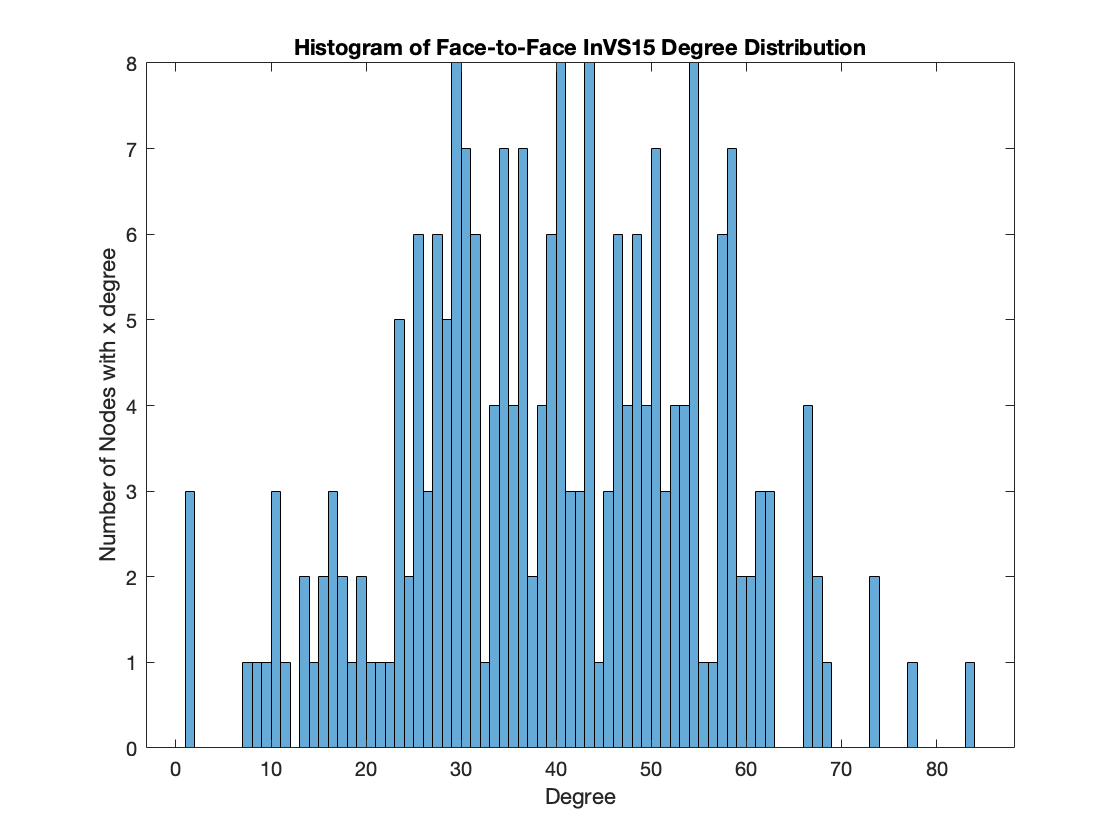

A_InVS15_DegreeDistributionHistogram = histogram(A_InVS15_DegreeDistribution);
A_InVS15_DegreeDistributionHistogram.BinWidth = 1;
xlabel('Degree');
ylabel('Number of Nodes with x degree');
title('Histogram of Face-to-Face InVS15 Degree Distribution');

disp(mean(A_InVS15_DegreeDistribution) + " " + std(A_InVS15_DegreeDistribution) + " " + var(A_InVS15_DegreeDistribution));

39.3917 15.6133 243.7764


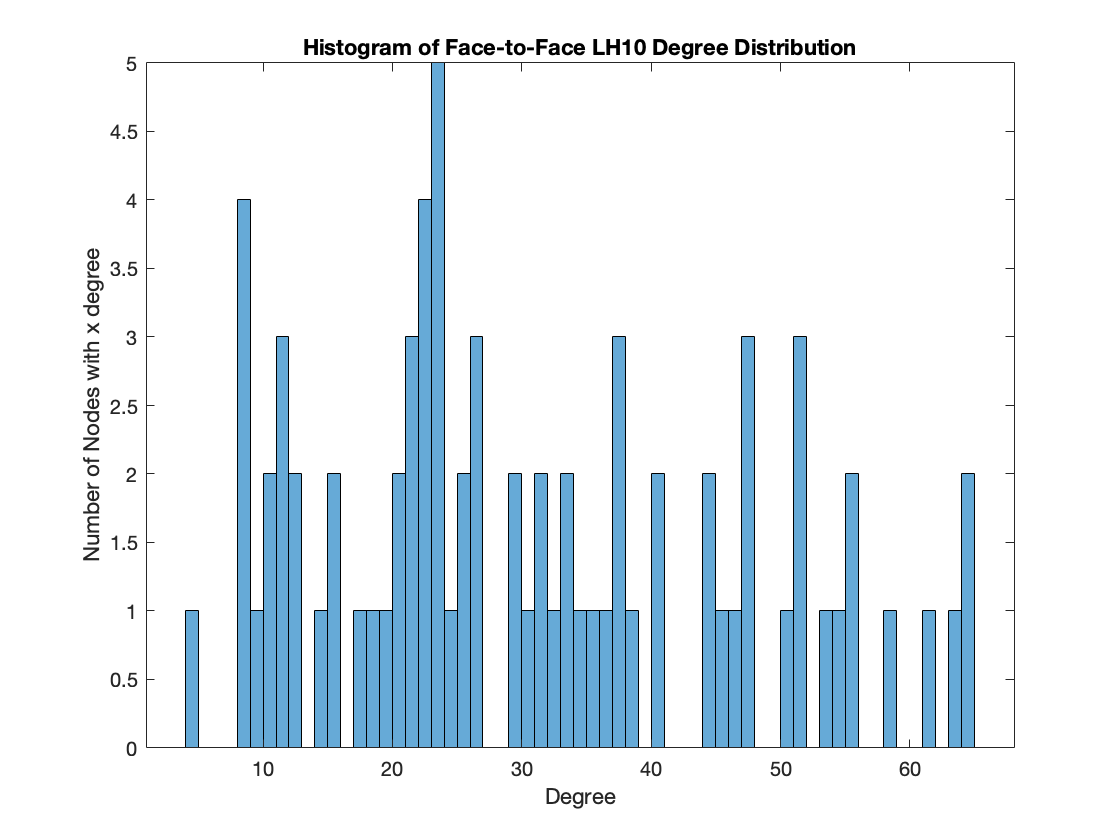

A_LH10_DegreeDistributionHistogram = histogram(A_LH10_DegreeDistribution);
A_LH10_DegreeDistributionHistogram.BinWidth = 1;
xlabel('Degree');
ylabel('Number of Nodes with x degree');
title('Histogram of Face-to-Face LH10 Degree Distribution');

disp(mean(A_LH10_DegreeDistribution) + " " + std(A_LH10_DegreeDistribution) + " " + var(A_LH10_DegreeDistribution));

30.4211 16.085 258.727


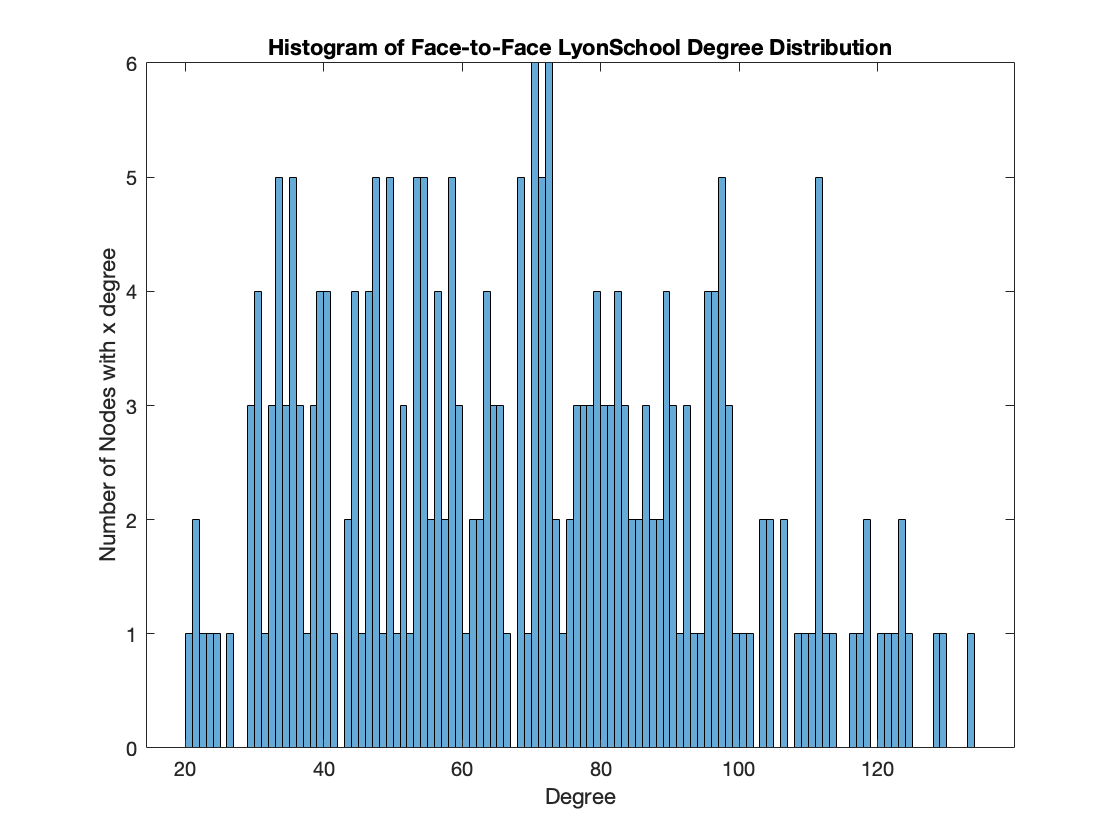

A_LyonSchool_DegreeDistributionHistogram = histogram(A_LyonSchool_DegreeDistribution);
A_LyonSchool_DegreeDistributionHistogram.BinWidth = 1;
xlabel('Degree');
ylabel('Number of Nodes with x degree');
title('Histogram of Face-to-Face LyonSchool Degree Distribution');

disp(mean(A_LyonSchool_DegreeDistribution) + " " + std(A_LyonSchool_DegreeDistribution) + " " + var(A_LyonSchool_DegreeDistribution));

68.7355 26.626 708.9422


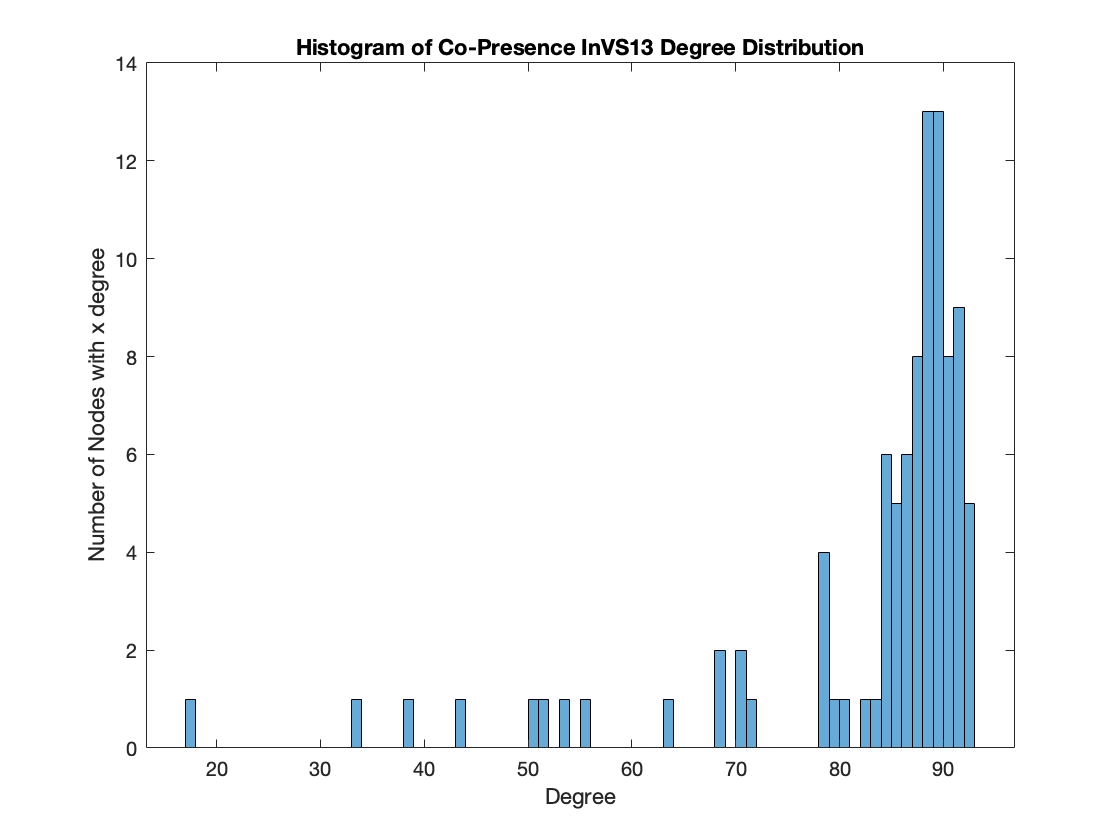

A_pres_InVS13_DegreeDistributionHistogram = histogram(A_pres_InVS13_DegreeDistribution);
A_pres_InVS13_DegreeDistributionHistogram.BinWidth = 1;
xlabel('Degree');
ylabel('Number of Nodes with x degree');
title('Histogram of Co-Presence InVS13 Degree Distribution');

disp(mean(A_pres_InVS13_DegreeDistribution) + " " + std(A_pres_InVS13_DegreeDistribution) + " " + var(A_pres_InVS13_DegreeDistribution));

82.4211 13.8898 192.9272


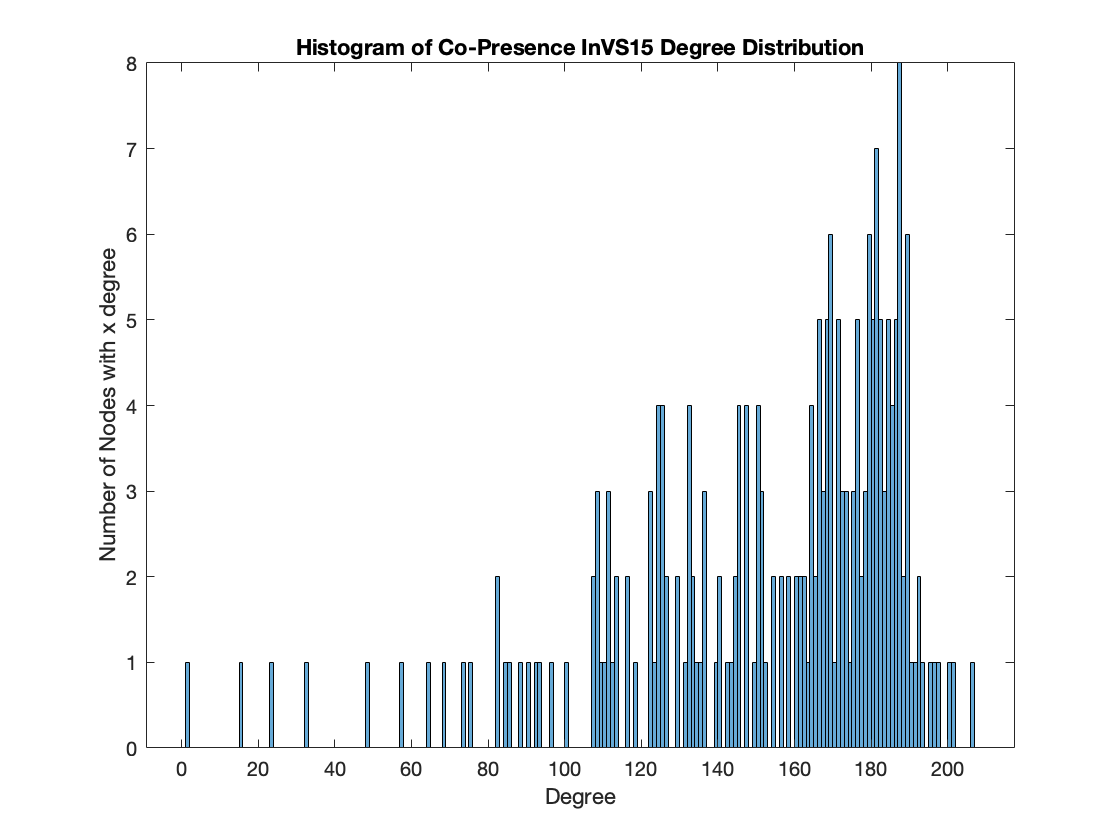

A_pres_InVS15_DegreeDistributionHistogram = histogram(A_pres_InVS15_DegreeDistribution);
A_pres_InVS15_DegreeDistributionHistogram.BinWidth = 1;
xlabel('Degree');
ylabel('Number of Nodes with x degree');
title('Histogram of Co-Presence InVS15 Degree Distribution');

disp(mean(A_pres_InVS15_DegreeDistribution) + " " + std(A_pres_InVS15_DegreeDistribution) + " " + var(A_pres_InVS15_DegreeDistribution));

152.7397 37.1716 1381.7255


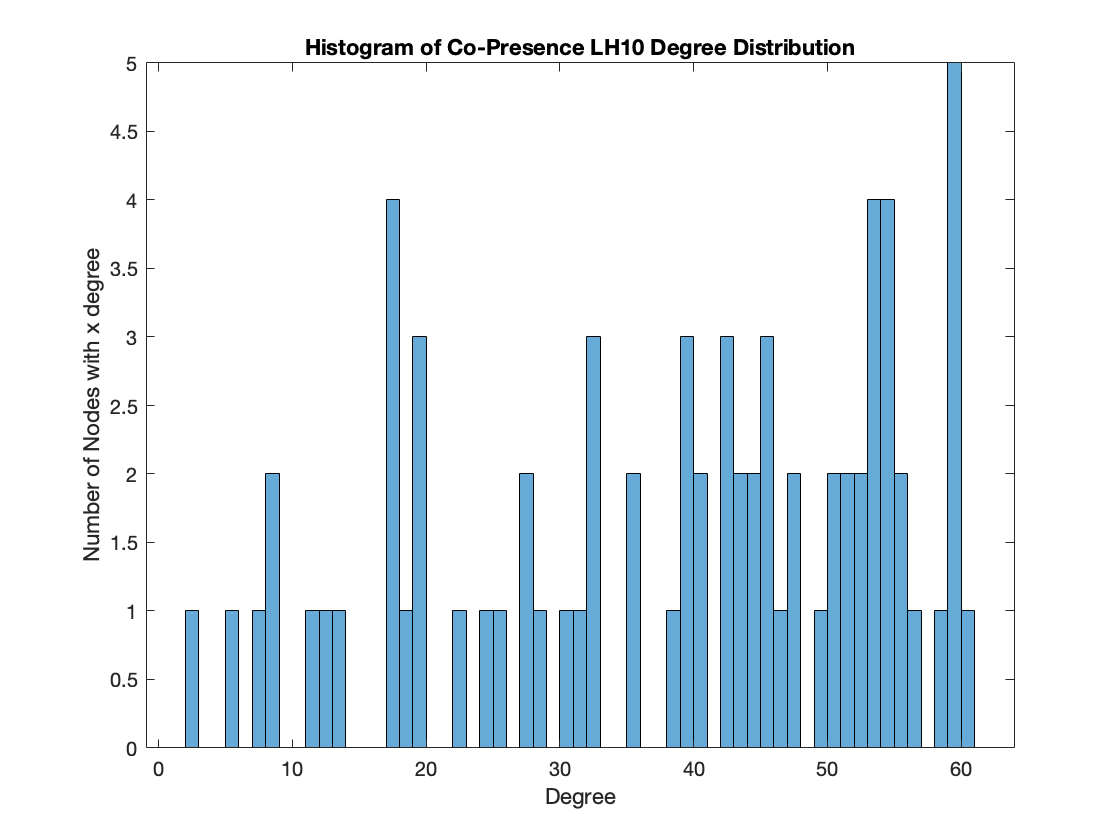

A_pres_LH10_DegreeDistributionHistogram = histogram(A_pres_LH10_DegreeDistribution);
A_pres_LH10_DegreeDistributionHistogram.BinWidth = 1;
xlabel('Degree');
ylabel('Number of Nodes with x degree');
title('Histogram of Co-Presence LH10 Degree Distribution');

disp(mean(A_pres_LH10_DegreeDistribution) + " " + std(A_pres_LH10_DegreeDistribution) + " " + var(A_pres_LH10_DegreeDistribution));

37.8356 16.3622 267.7226


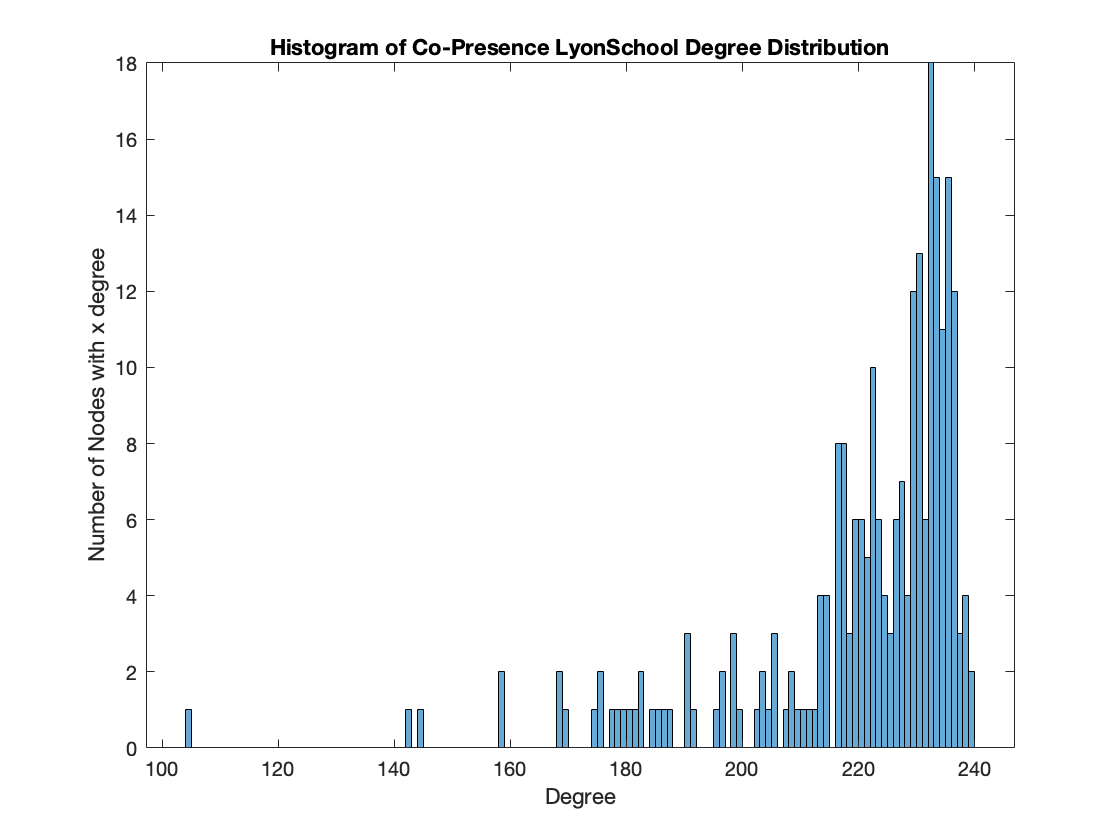

A_pres_LyonSchool_DegreeDistributionHistogram = histogram(A_pres_LyonSchool_DegreeDistribution);
A_pres_LyonSchool_DegreeDistributionHistogram.BinWidth = 1;
xlabel('Degree');
ylabel('Number of Nodes with x degree');
title('Histogram of Co-Presence LyonSchool Degree Distribution');

disp(mean(A_pres_LyonSchool_DegreeDistribution) + " " + std(A_pres_LyonSchool_DegreeDistribution) + " " + var(A_pres_LyonSchool_DegreeDistribution));

219.7851 19.788 391.5636


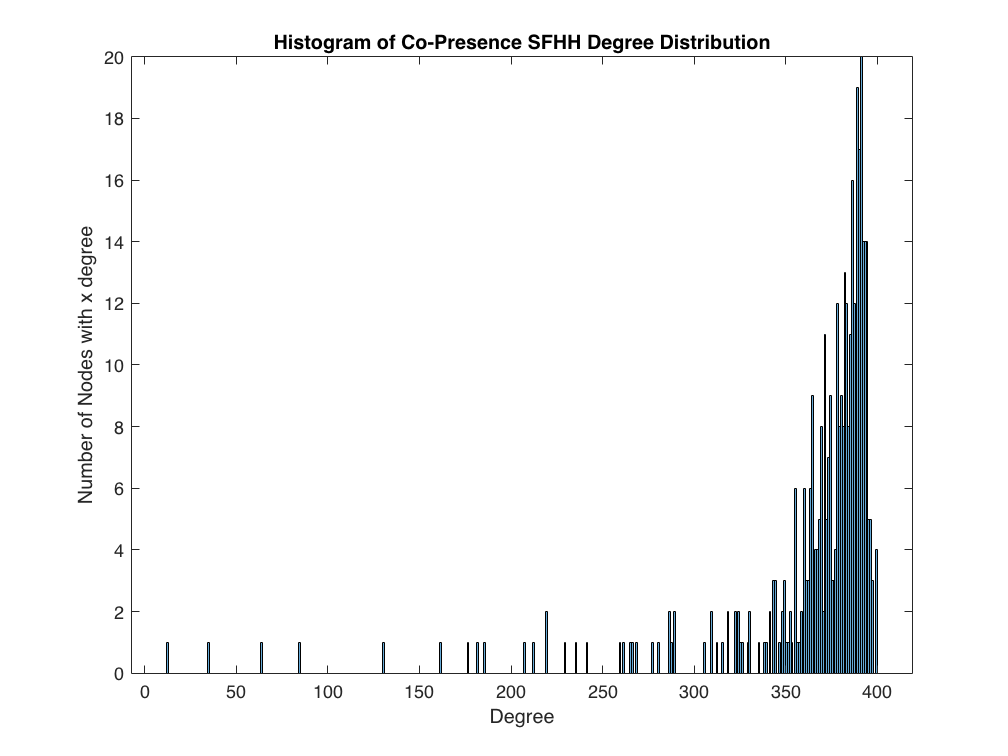

A_pres_SFHH_DegreeDistributionHistogram = histogram(A_pres_SFHH_DegreeDistribution);
A_pres_SFHH_DegreeDistributionHistogram.BinWidth = 1;
xlabel('Degree');
ylabel('Number of Nodes with x degree');
title('Histogram of Co-Presence SFHH Degree Distribution');

disp(mean(A_pres_SFHH_DegreeDistribution) + " " + std(A_pres_SFHH_DegreeDistribution) + " " + var(A_pres_SFHH_DegreeDistribution));

365.0471 50.196 2519.6421


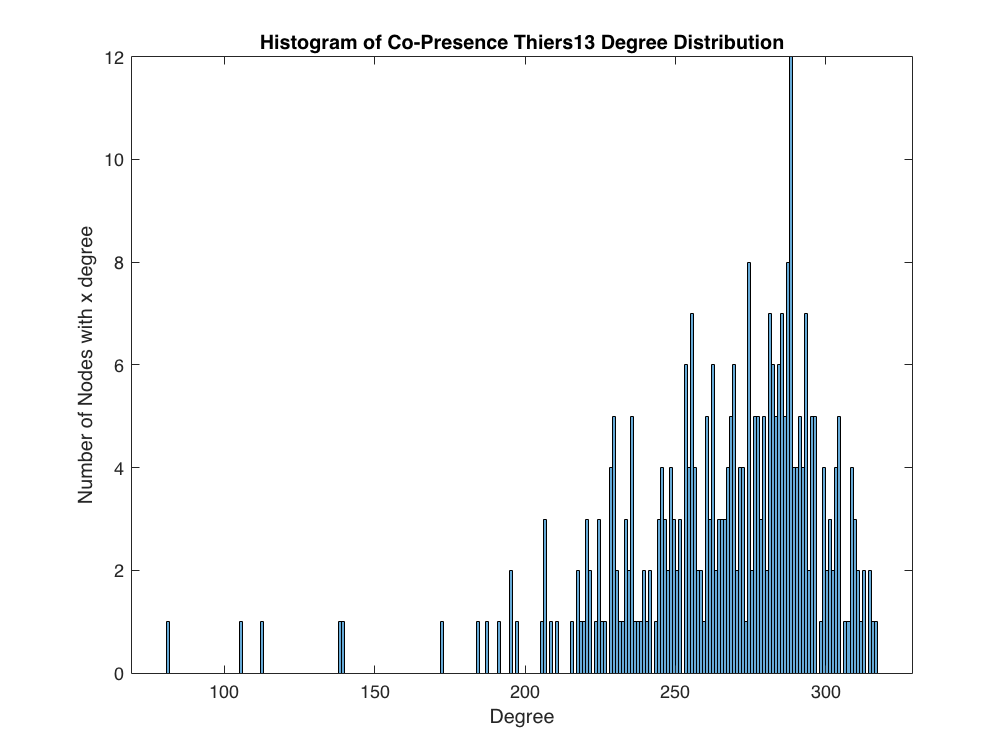

A_pres_Thiers13_DegreeDistributionHistogram = histogram(A_pres_Thiers13_DegreeDistribution);
A_pres_Thiers13_DegreeDistributionHistogram.BinWidth = 1;
xlabel('Degree');
ylabel('Number of Nodes with x degree');
title('Histogram of Co-Presence Thiers13 Degree Distribution');

disp(mean(A_pres_Thiers13_DegreeDistribution) + " " + std(A_pres_Thiers13_DegreeDistribution) + " " + var(A_pres_Thiers13_DegreeDistribution));

265.2195 33.6613 1133.0832


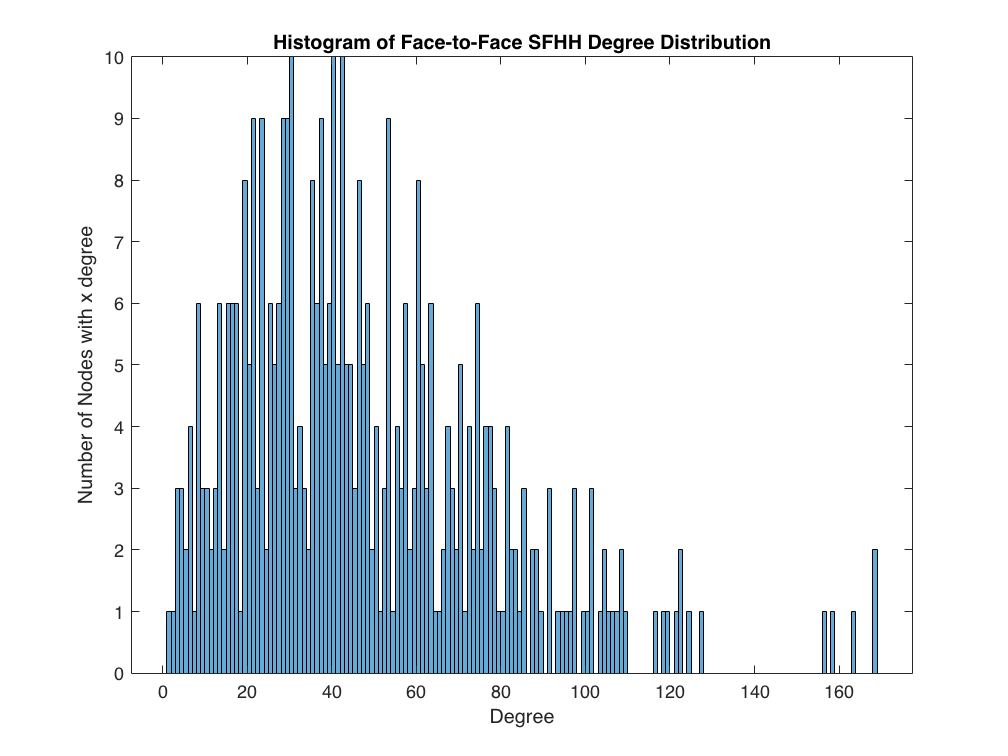

A_SFHH_DegreeDistributionHistogram = histogram(A_SFHH_DegreeDistribution);
A_SFHH_DegreeDistributionHistogram.BinWidth = 1;
xlabel('Degree');
ylabel('Number of Nodes with x degree');
title('Histogram of Face-to-Face SFHH Degree Distribution');

disp(mean(A_SFHH_DegreeDistribution) + " " + std(A_SFHH_DegreeDistribution) + " " + var(A_SFHH_DegreeDistribution));

47.469 30.1809 910.8865


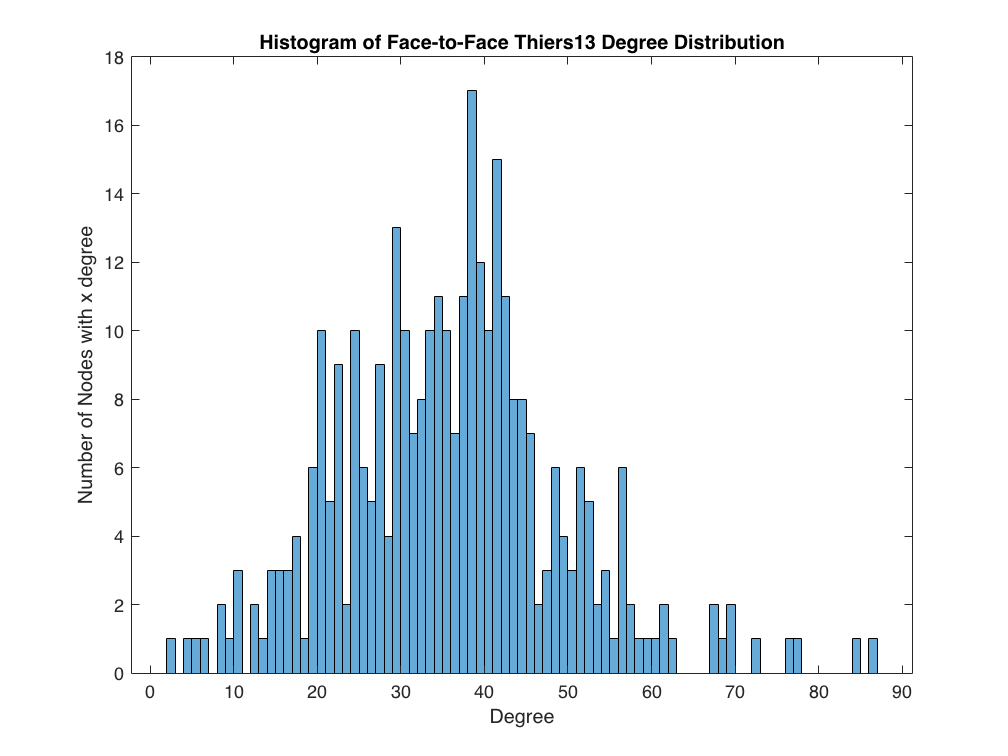

A_Thiers13_DegreeDistributionHistogram = histogram(A_Thiers13_DegreeDistribution);
A_Thiers13_DegreeDistributionHistogram.BinWidth = 1;
xlabel('Degree');
ylabel('Number of Nodes with x degree');
title('Histogram of Face-to-Face Thiers13 Degree Distribution');

disp(mean(A_Thiers13_DegreeDistribution) + " " + std(A_Thiers13_DegreeDistribution) + " " + var(A_Thiers13_DegreeDistribution));

35.5841 13.5182 182.7406


## **Calculating the Clustering Coefficient**

In order to calculate the clustering coefficient we need to multiply 2 by the cube of the database for that vertex/node (the number of paths of length 3 for that vertex/node). Then we have to divide this value by the degree of the vertex/node and the degree of the vertex/node minus 1.


$$\textrm{cc}\left(v\right)=\frac{\left(2|\Delta v|\right)}{\deg \left(v\right)\left(\deg \left(v\right)-1\right)}$$


A_InVS13_ClusteringCoefficient = rdivide(2 * transpose(diag(A_InVS13^3)), times(A_InVS13_DegreeDistribution, A_InVS13_DegreeDistribution - 1));
A_InVS15_ClusteringCoefficient = rdivide(2 * transpose(diag(A_InVS15^3)), times(A_InVS15_DegreeDistribution, A_InVS15_DegreeDistribution - 1));
A_LH10_ClusteringCoefficient = rdivide(2 * transpose(diag(A_LH10^3)), times(A_LH10_DegreeDistribution, A_LH10_DegreeDistribution - 1));
A_LyonSchool_ClusteringCoefficient = rdivide(2 * transpose(diag(A_LyonSchool^3)), times(A_LyonSchool_DegreeDistribution, A_LyonSchool_DegreeDistribution - 1));
A_pres_InVS13_ClusteringCoefficient = rdivide(2 * transpose(diag(A_pres_InVS13^3)), times(A_pres_InVS13_DegreeDistribution, A_pres_InVS13_DegreeDistribution - 1));
A_pres_InVS15_ClusteringCoefficient = rdivide(2 * transpose(diag(A_pres_InVS15^3)), times(A_pres_InVS15_DegreeDistribution, A_pres_InVS15_DegreeDistribution - 1));
A_pres_LH10_ClusteringCoefficient = rdivide(2 * transpose(diag(A_pres_LH10^3)), times(A_pres_LH10_DegreeDistribution, A_pres_LH10_DegreeDistribution - 1));
A_pres_LyonSchool_ClusteringCoefficient = rdivide(2 * transpose(diag(A_pres_LyonSchool^3)), times(A_pres_LyonSchool_DegreeDistribution, A_pres_LyonSchool_DegreeDistribution - 1));
A_pres_SFHH_ClusteringCoefficient = rdivide(2 * transpose(diag(A_pres_SFHH^3)), times(A_pres_SFHH_DegreeDistribution, A_pres_SFHH_DegreeDistribution - 1));
A_pres_Thiers13_ClusteringCoefficient = rdivide(2 * transpose(diag(A_pres_Thiers13^3)), times(A_pres_Thiers13_DegreeDistribution, A_pres_Thiers13_DegreeDistribution - 1));
A_SFHH_ClusteringCoefficient = rdivide(2 * transpose(diag(A_SFHH^3)), times(A_SFHH_DegreeDistribution, A_SFHH_DegreeDistribution - 1));
A_Thiers13_ClusteringCoefficient = rdivide(2 * transpose(diag(A_Thiers13^3)), times(A_Thiers13_DegreeDistribution, A_Thiers13_DegreeDistribution - 1));

Placing a 0 in all NaN for clusterin coefficient:

A_InVS13_ClusteringCoefficient(isnan(A_InVS13_ClusteringCoefficient))=0

A_InVS13_ClusteringCoefficient =     1.5238    1.2000    0.7238    0.7029    1.0606    0.6800    1.1538    1.0190    0.4762    0.5026    1.2857    0.6476    0.6108    0.3333    0.6855    1.0256    0.6316    0.6667    1.0095    0.6784    0.7778    0.5810    0.8225    0.9455    0.5415    0.6912    0.4396    0.5793    0.6320    0.7843    0.7794    0.5152    0.7238    1.2308    0.9333    0.7524    1.5238    0.8286    0.6765    0.8382    0.8105    1.0000    0.8366    0.9524    0.7000    0.6720    0.9143    1.2000    0.6167    0.6737


A_InVS15_ClusteringCoefficient(isnan(A_InVS15_ClusteringCoefficient))=0

A_InVS15_ClusteringCoefficient =          0    0.8121    0.6000    0.6906    0.5408    0.8082    0.7778    0.8583    0.6154    0.6976    0.8188    0.9328    0.6373    0.7146    0.9365         0    1.0200    0.7556    0.5805    0.7573    0.6423    0.8430    1.0708    0.9527    0.8595    0.5989    0.8676    0.5333    0.6594    0.5846    0.6915    0.6220    0.7037    0.7264    0.9058    0.6733    0.7517    0.7979    0.8483    0.8128    0.6032    0.8000    0.9690    1.2821    0.8026    0.6000    0.8857    0.5911    0.6991    0.6497


A_LH10_ClusteringCoefficient(isnan(A_LH10_ClusteringCoefficient))=0

A_LH10_ClusteringCoefficient =     1.0466    1.4879    1.6333    1.4108    1.1498    1.3864    1.0650    1.4267    1.1922    1.1771    1.3556    1.3423    1.1325    1.2044    0.9923    1.4372    1.3298    1.2769    1.3287    1.3030    1.1137    1.2808    1.0731    1.2077    1.0856    1.7229    1.1111    1.2081    1.5671    0.9091    1.3531    0.7576    1.3298    1.2059    1.0896    1.3333    1.3905    1.6000    1.9286    1.6206    2.0000    1.2000    1.4545    1.4971    1.2692    1.7333    1.5573    1.9341    1.3042    1.3505


A_LyonSchool_ClusteringCoefficient(isnan(A_LyonSchool_ClusteringCoefficient))=0

A_LyonSchool_ClusteringCoefficient =     1.0602    1.1471    1.0804    1.0377    1.3694    1.0197    0.8936    1.4575    0.9518    1.0765    1.6976    0.9447    0.9985    1.0369    1.0739    0.9052    0.8496    1.0159    0.9592    1.1038    0.9323    1.2046    1.1072    0.8571    1.0825    0.9039    1.0920    1.1565    1.0962    0.9916    1.0491    0.9082    0.8773    0.9335    1.0512    1.0723    0.8719    1.1326    1.4602    0.9260    1.0537    1.0227    0.9385    0.9859    1.8498    1.0157    1.0204    0.9752    0.9596    1.6000


A_pres_InVS13_ClusteringCoefficient(isnan(A_pres_InVS13_ClusteringCoefficient))=0

A_pres_InVS13_ClusteringCoefficient =     1.9428    1.8917    1.8694    1.7901    1.8202    1.8056    1.8325    1.8315    1.8027    1.8232    1.9935    1.8117    1.8709    1.8321    2.0000    1.8247    1.9053    1.8322    1.8247    1.8345    1.8841    1.8917    1.7691    1.8605    1.8979    1.8485    1.8279    1.8168    1.8485    1.8647    1.8391    1.8182    1.8872    1.8242    1.8738    1.8422    1.8447    1.9010    1.8292    1.8534    1.8437    1.8471    1.9118    1.9106    1.8352    1.8452    1.8537    1.8361    1.9076    1.7905


A_pres_InVS15_ClusteringCoefficient(isnan(A_pres_InVS15_ClusteringCoefficient))=0

A_pres_InVS15_ClusteringCoefficient =     1.7208    1.5579    1.6387    1.5360    1.5894    1.6087    1.7240    1.6207    1.6411    1.5617    1.6502    1.6043    1.6769    1.6283    1.6290    1.6520    1.7847    1.5740    1.5306    1.5555    1.5751    1.5621    1.6855    1.5780    1.5793    1.5786    1.8720    1.6605    1.5781    1.5691    1.5325    1.5403    1.5072    1.5591    1.6463    1.5703    1.5898    1.5281    1.6060    1.5511    1.6093    1.6339    1.7103    1.6041    1.5447    1.5130    1.6232    1.7913    1.6071    1.5912


A_pres_LH10_ClusteringCoefficient(isnan(A_pres_LH10_ClusteringCoefficient))=0

A_pres_LH10_ClusteringCoefficient =     1.4978    1.5273    1.8266    1.6376    1.4049    1.5924    1.4249    1.3473    1.4235    1.3875    1.3244    1.8468    1.4411    1.3279    1.3795    1.3829    1.6934    1.3636    1.5470    1.6221    1.6081    1.7379    1.3864    1.3513    1.6367    1.4325    1.4766    1.5027    1.5562    1.4035    1.4612    1.2059    1.5514    1.4667    1.3524    1.7692    1.4667    1.5201    1.2857    1.3508    1.6645    1.5870    1.4949    1.4684    1.5261    1.7550    1.4709    1.8571    1.2131    2.0000


A_pres_LyonSchool_ClusteringCoefficient(isnan(A_pres_LyonSchool_ClusteringCoefficient))=0

A_pres_LyonSchool_ClusteringCoefficient =     1.8626    1.8201    1.8924    1.8521    1.8816    1.8603    1.8778    1.8667    1.8580    1.8631    1.8642    1.8372    1.8378    1.8702    1.8702    1.8663    1.8702    1.8702    1.8669    1.8649    1.8510    1.8775    1.8693    1.8573    1.8702    1.8598    1.8686    1.8635    1.8619    1.8784    1.8594    1.8702    1.8758    1.8712    1.8763    1.8758    1.8657    1.8724    1.8912    1.8702    1.8511    1.8679    1.8363    1.8594    1.8497    1.8619    1.8749    1.8728    1.8432    1.8581


A_pres_SFHH_ClusteringCoefficient(isnan(A_pres_SFHH_ClusteringCoefficient))=0

A_pres_SFHH_ClusteringCoefficient =     1.9015    1.8822    1.8778    1.8658    1.8713    1.8843    1.8832    1.9259    1.8516    1.9117    1.9604    1.8526    1.8627    1.8720    1.8627    1.8635    1.8612    1.8907    1.8732    1.9370    1.8847    1.8436    1.8861    1.8651    1.8628    1.8787    1.8805    1.8400    1.8683    1.8695    1.8851    1.8662    1.8509    1.8681    1.8733    1.9230    1.8800    1.8982    1.8682    1.8841    1.8812    1.9159    1.9006    1.8954    1.9175    1.8841    1.9057    1.9115    1.9112    1.9044


A_pres_Thiers13_ClusteringCoefficient(isnan(A_pres_Thiers13_ClusteringCoefficient))=0

A_pres_Thiers13_ClusteringCoefficient =     1.8294    1.9150    1.7043    1.6801    1.6422    1.6714    1.6652    1.6768    1.6978    1.6855    1.6802    1.6876    1.7071    1.6865    1.7378    1.6794    1.6542    1.6646    1.7075    1.7005    1.6829    1.7148    1.6660    1.6583    1.9451    1.6588    1.6921    1.6964    1.6586    1.6616    1.6399    1.6621    1.6861    1.6718    1.6620    1.7039    1.6656    1.7101    1.6834    1.6393    1.6842    1.6866    1.6875    1.7067    1.7167    1.6789    1.6738    1.6637    1.6849    1.6757


A_SFHH_ClusteringCoefficient(isnan(A_SFHH_ClusteringCoefficient))=0

A_SFHH_ClusteringCoefficient =     0.6561    0.4672    0.5591    0.4077    0.5189    0.9744    0.6857    0.5377    0.4809    0.4667    0.9710    0.4500    0.4505    0.5449    0.5000    0.3714    0.5495    0.6090    0.6286    0.5905    0.4013    0.7143    0.4524    0.4858    0.5646    0.5442    0.6895    0.4224    0.4723    0.7238    0.5813    0.5520    0.4938    0.4828    0.4884    0.4468    0.5072    0.7485    0.5356    0.5141    0.3971    0.4993    0.5333    0.6167    0.4526    0.4619    0.5022    0.5993    0.5835    0.5172


A_Thiers13_ClusteringCoefficient(isnan(A_Thiers13_ClusteringCoefficient))=0

A_Thiers13_ClusteringCoefficient =     1.4862    0.6935    0.9513    0.6436    1.0697    1.3751    0.8344    1.4286    0.9900    0.8878    0.8841    0.9626    0.6967    0.9748    0.8202    0.6716    0.9662    1.2762    1.1290    0.9488    1.5608    0.8130    0.7529    2.0000    0.8566    0.9825    1.0901    1.4566    0.7382    0.9805    1.2093    0.9280    1.0989    1.1684    0.7756    1.1829    0.8869    0.9091    0.5111    0.9132    1.0000    1.1687    1.1359    1.1359    1.0909    0.7602    0.9175    0.6878    0.8403    0.7597


Calculating Clustering Coefficient Average for each location:

A_InVS13_ClusteringCoefficientAverage = mean(A_InVS13_ClusteringCoefficient);
A_InVS15_ClusteringCoefficientAverage = mean(A_InVS15_ClusteringCoefficient);
A_LH10_ClusteringCoefficientAverage = mean(A_LH10_ClusteringCoefficient);
A_LyonSchool_ClusteringCoefficientAverage = mean(A_LyonSchool_ClusteringCoefficient);
A_pres_InVS13_ClusteringCoefficientAverage = mean(A_pres_InVS13_ClusteringCoefficient);
A_pres_InVS15_ClusteringCoefficientAverage = mean(A_pres_InVS15_ClusteringCoefficient);
A_pres_LH10_ClusteringCoefficientAverage = mean(A_pres_LH10_ClusteringCoefficient);
A_pres_LyonSchool_ClusteringCoefficientAverage = mean(A_pres_LyonSchool_ClusteringCoefficient);
A_pres_SFHH_ClusteringCoefficientAverage = mean(A_pres_SFHH_ClusteringCoefficient);
A_pres_Thiers13_ClusteringCoefficientAverage = mean(A_pres_Thiers13_ClusteringCoefficient);
A_SFHH_ClusteringCoefficientAverage = mean(A_SFHH_ClusteringCoefficient);
A_Thiers13_ClusteringCoefficientAverage = mean(A_Thiers13_ClusteringCoefficient);

Clustering Coefficient plots:

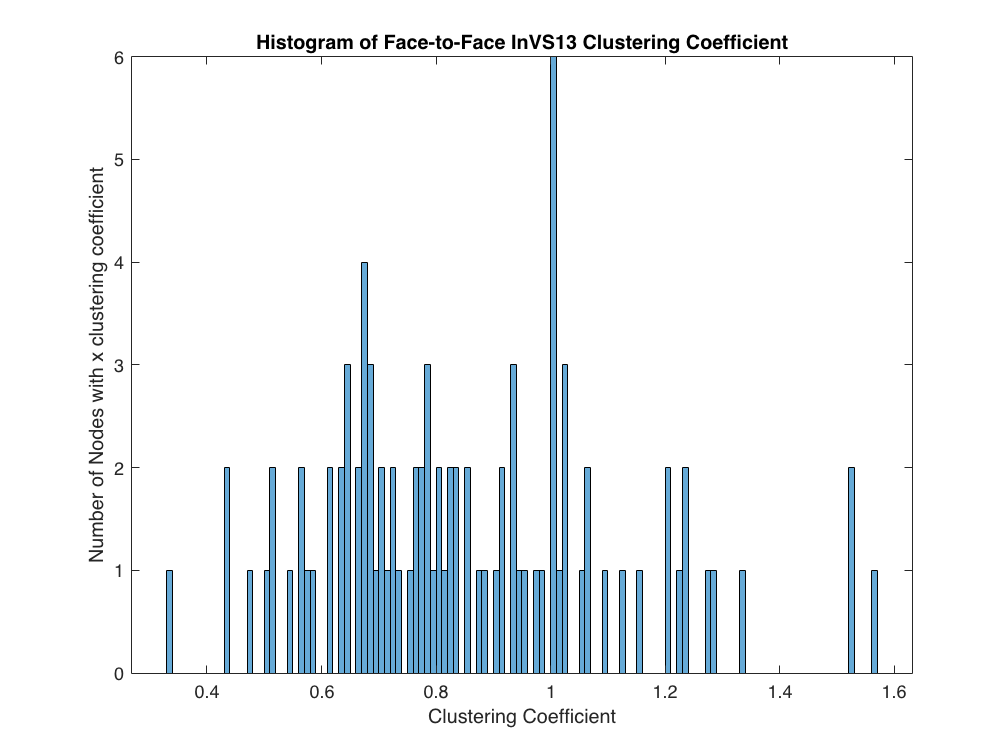

A_InVS13_ClusteringCoefficientHistogram = histogram(A_InVS13_ClusteringCoefficient);
A_InVS13_ClusteringCoefficientHistogram.BinWidth = 0.01;
xlabel('Clustering Coefficient')
ylabel('Number of Nodes with x clustering coefficient')
title('Histogram of Face-to-Face InVS13 Clustering Coefficient');

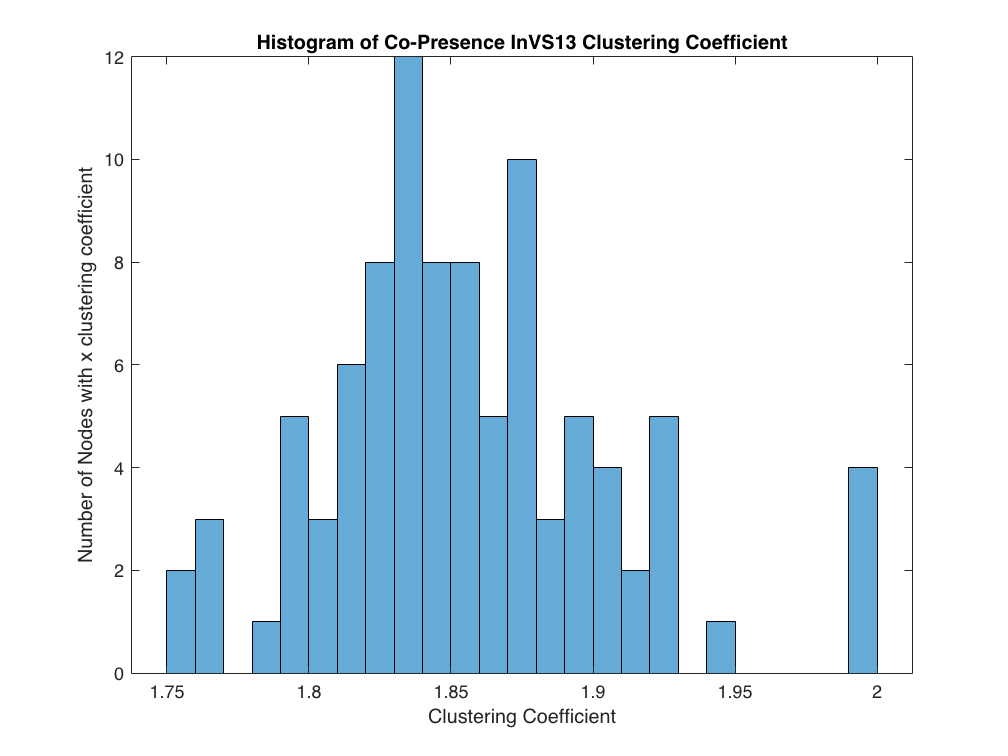

A_pres_InVS13_ClusteringCoefficientHistogram = histogram(A_pres_InVS13_ClusteringCoefficient);
A_pres_InVS13_ClusteringCoefficientHistogram.BinWidth = 0.01;
xlabel('Clustering Coefficient')
ylabel('Number of Nodes with x clustering coefficient')
title('Histogram of Co-Presence InVS13 Clustering Coefficient');

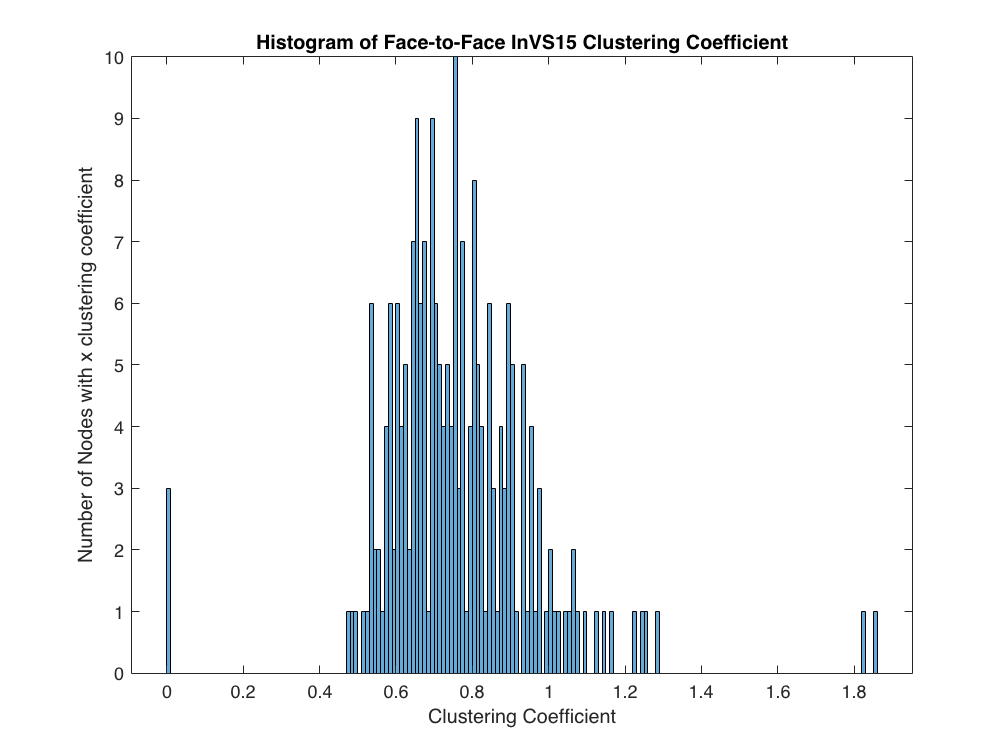

A_InVS15_ClusteringCoefficientHistogram = histogram(A_InVS15_ClusteringCoefficient);
A_InVS15_ClusteringCoefficientHistogram.BinWidth = 0.01;
xlabel('Clustering Coefficient')
ylabel('Number of Nodes with x clustering coefficient')
title('Histogram of Face-to-Face InVS15 Clustering Coefficient');

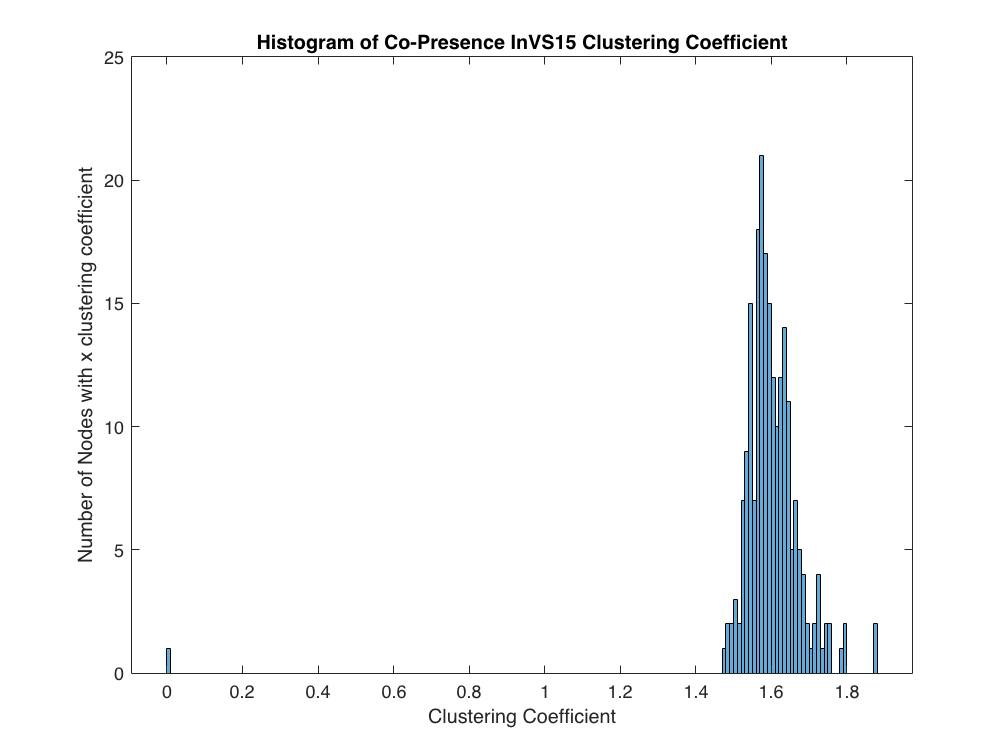

A_pres_InVS15_ClusteringCoefficientHistogram = histogram(A_pres_InVS15_ClusteringCoefficient);
A_pres_InVS15_ClusteringCoefficientHistogram.BinWidth = 0.01;
xlabel('Clustering Coefficient')
ylabel('Number of Nodes with x clustering coefficient')
title('Histogram of Co-Presence InVS15 Clustering Coefficient');

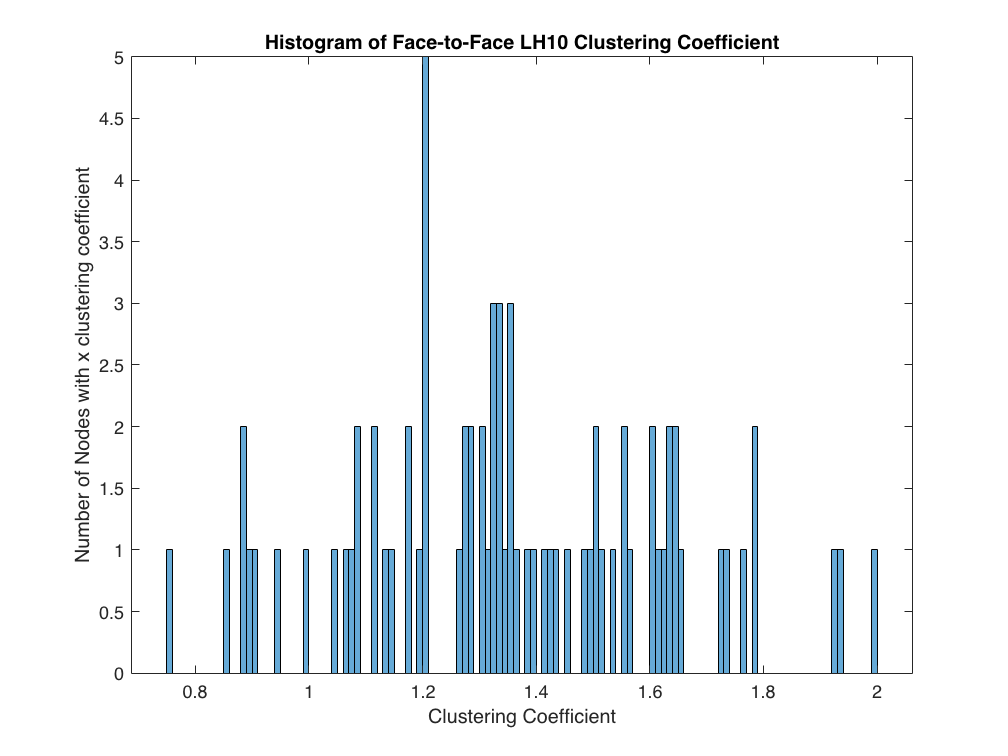

A_LH10_ClusteringCoefficientHistogram = histogram(A_LH10_ClusteringCoefficient);
A_LH10_ClusteringCoefficientHistogram.BinWidth = 0.01;
xlabel('Clustering Coefficient')
ylabel('Number of Nodes with x clustering coefficient')
title('Histogram of Face-to-Face LH10 Clustering Coefficient');

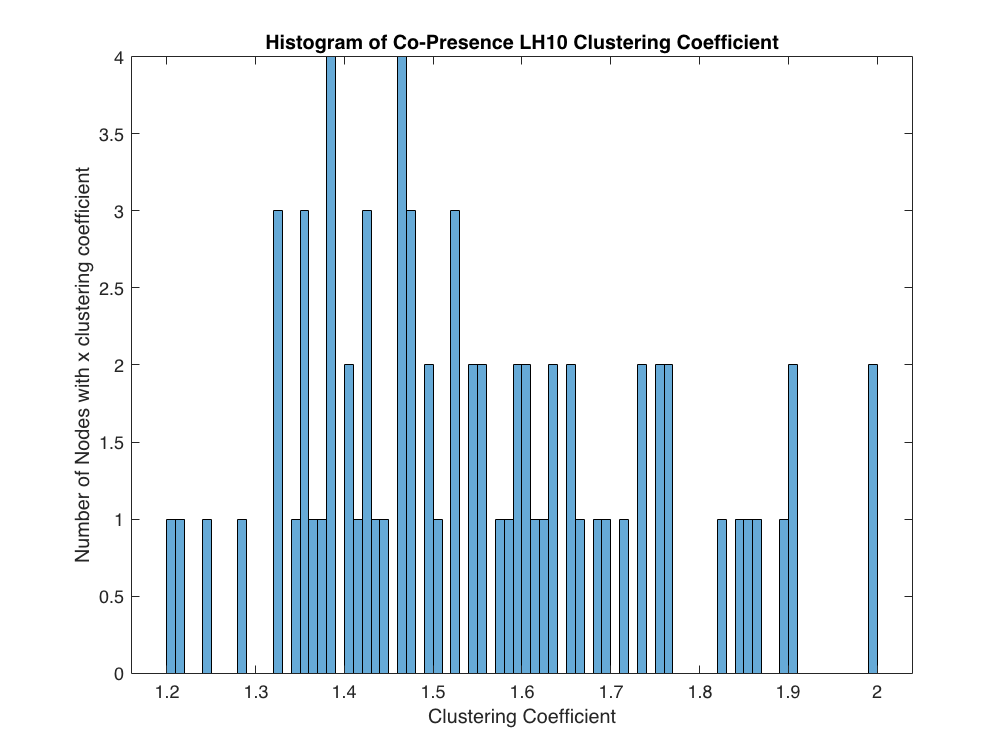

A_pres_LH10_ClusteringCoefficientHistogram = histogram(A_pres_LH10_ClusteringCoefficient);
A_pres_LH10_ClusteringCoefficientHistogram.BinWidth = 0.01;
xlabel('Clustering Coefficient')
ylabel('Number of Nodes with x clustering coefficient')
title('Histogram of Co-Presence LH10 Clustering Coefficient');

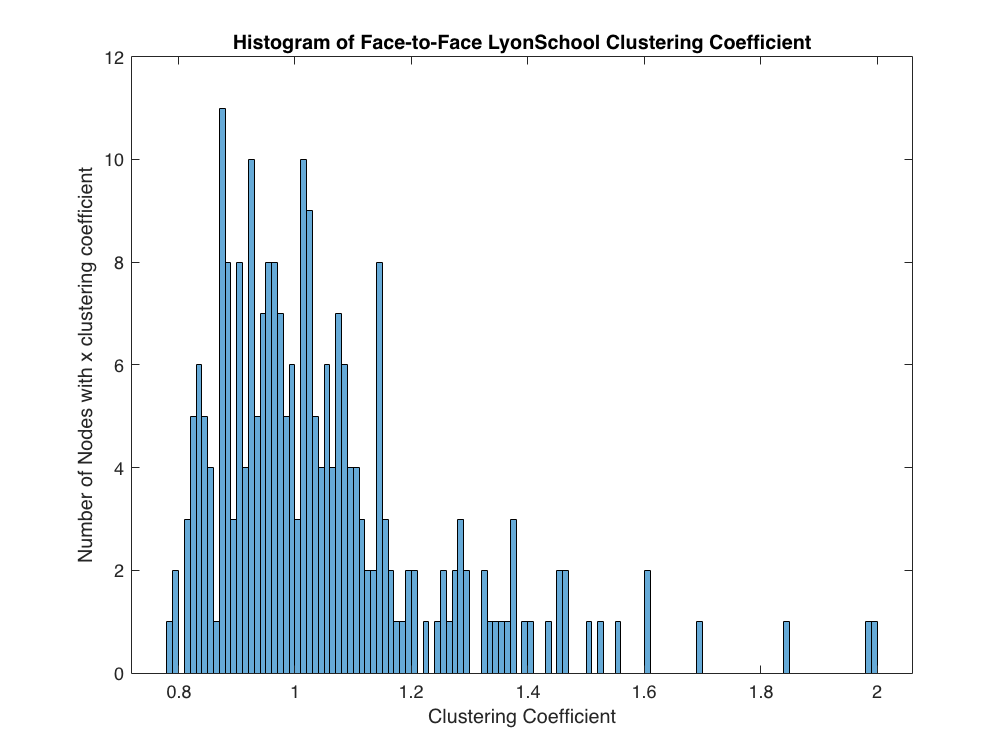

A_LyonSchool_ClusteringCoefficientHistogram = histogram(A_LyonSchool_ClusteringCoefficient);
A_LyonSchool_ClusteringCoefficientHistogram.BinWidth = 0.01;
xlabel('Clustering Coefficient')
ylabel('Number of Nodes with x clustering coefficient')
title('Histogram of Face-to-Face LyonSchool Clustering Coefficient');

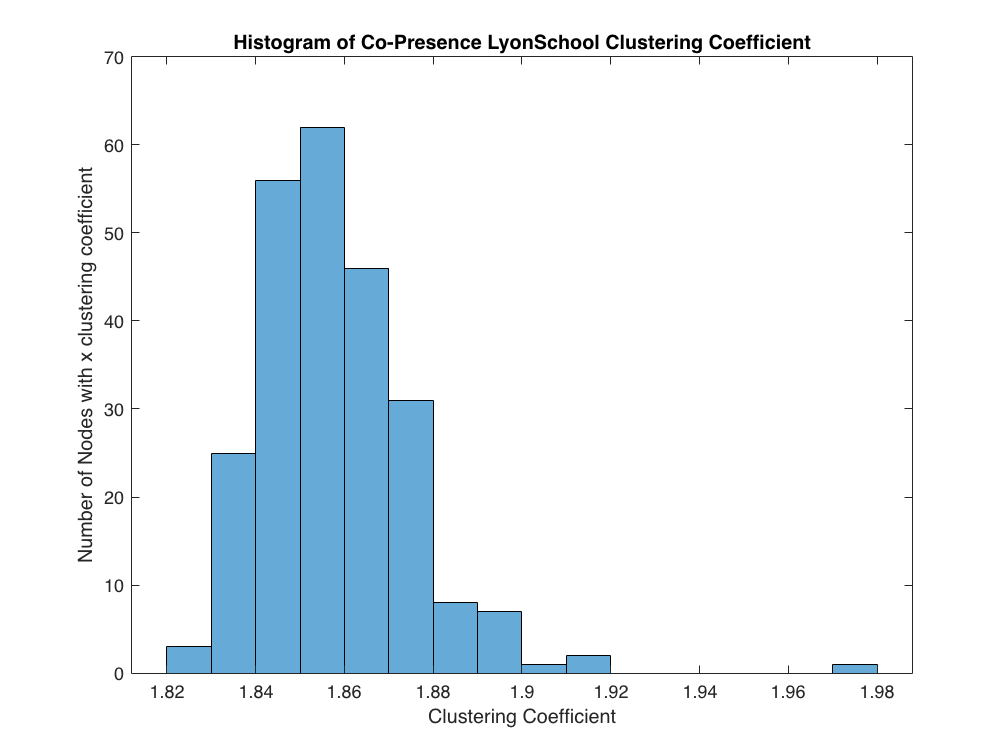

A_pres_LyonSchool_ClusteringCoefficientHistogram = histogram(A_pres_LyonSchool_ClusteringCoefficient);
A_pres_LyonSchool_ClusteringCoefficientHistogram.BinWidth = 0.01;
xlabel('Clustering Coefficient')
ylabel('Number of Nodes with x clustering coefficient')
title('Histogram of Co-Presence LyonSchool Clustering Coefficient');

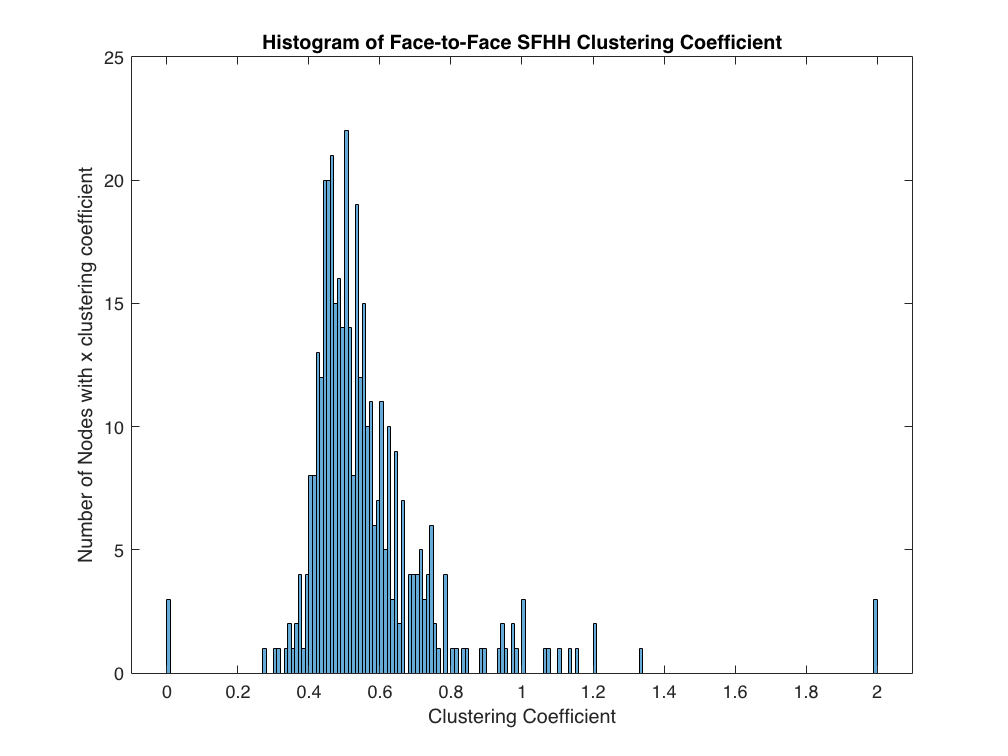

A_SFHH_ClusteringCoefficientHistogram = histogram(A_SFHH_ClusteringCoefficient);
A_SFHH_ClusteringCoefficientHistogram.BinWidth = 0.01;
xlabel('Clustering Coefficient')
ylabel('Number of Nodes with x clustering coefficient')
title('Histogram of Face-to-Face SFHH Clustering Coefficient');

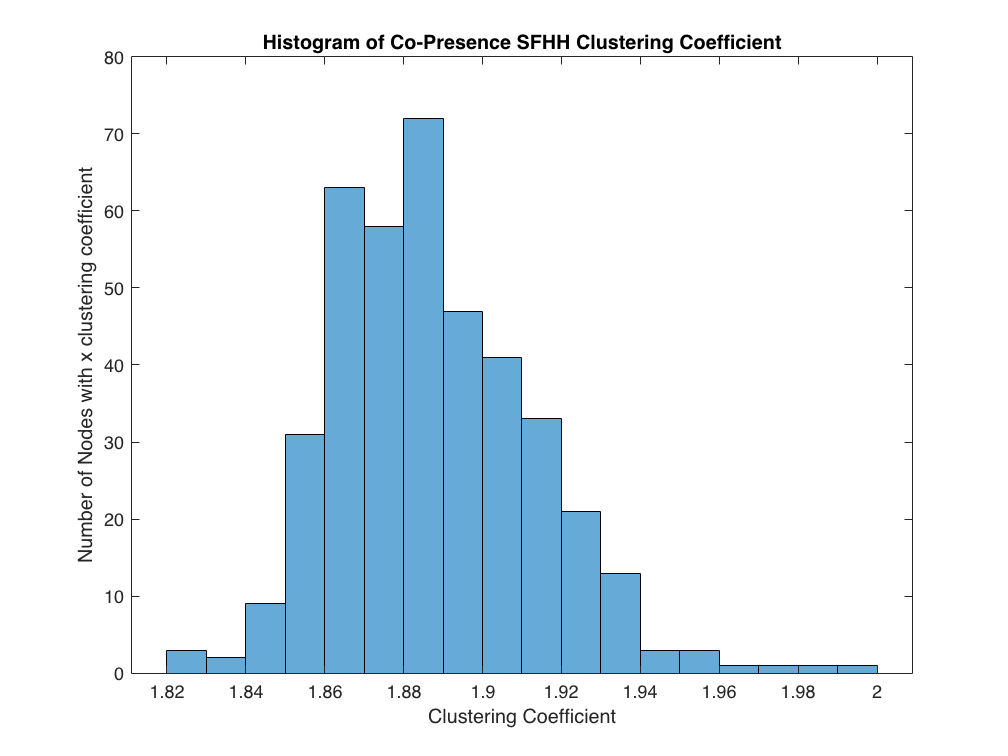

A_pres_SFHH_ClusteringCoefficientHistogram = histogram(A_pres_SFHH_ClusteringCoefficient);
A_pres_SFHH_ClusteringCoefficientHistogram.BinWidth = 0.01;
xlabel('Clustering Coefficient')
ylabel('Number of Nodes with x clustering coefficient')
title('Histogram of Co-Presence SFHH Clustering Coefficient');

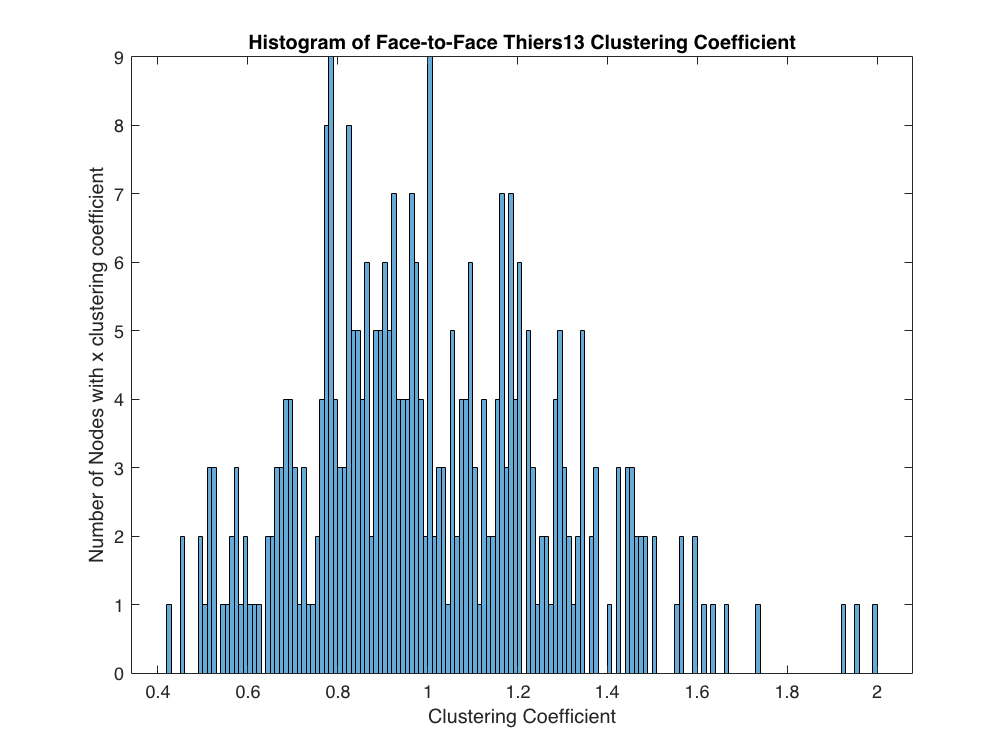

A_Thiers13_ClusteringCoefficientHistogram = histogram(A_Thiers13_ClusteringCoefficient);
A_Thiers13_ClusteringCoefficientHistogram.BinWidth = 0.01;
xlabel('Clustering Coefficient')
ylabel('Number of Nodes with x clustering coefficient')
title('Histogram of Face-to-Face Thiers13 Clustering Coefficient');

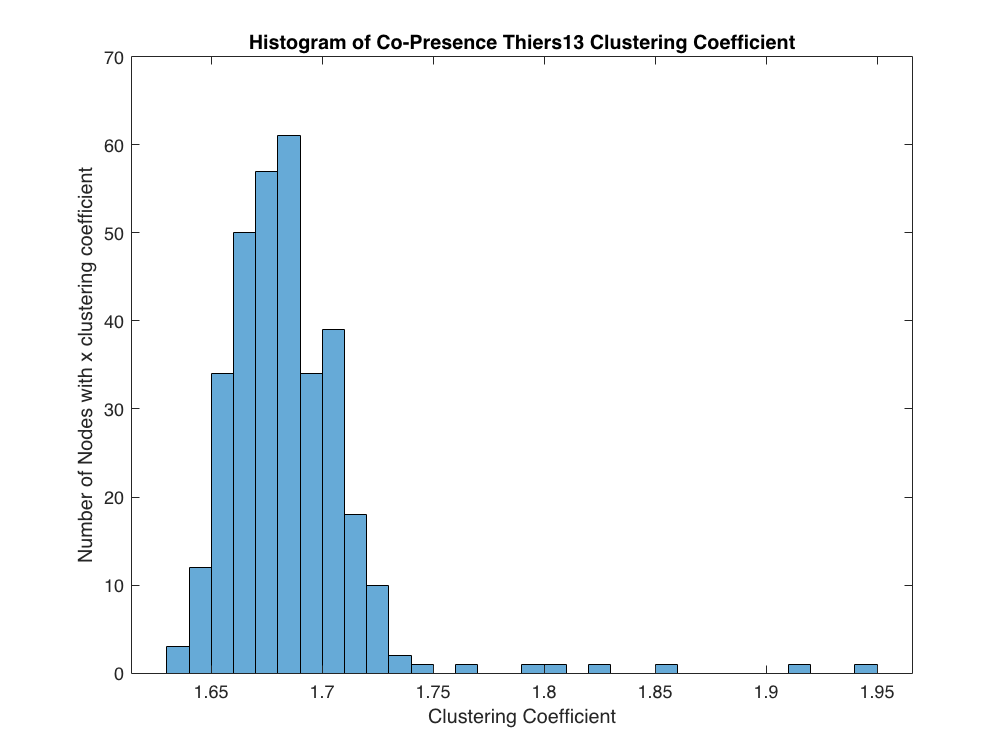

A_pres_Thiers13_ClusteringCoefficientHistogram = histogram(A_pres_Thiers13_ClusteringCoefficient);
A_pres_Thiers13_ClusteringCoefficientHistogram.BinWidth = 0.01;
xlabel('Clustering Coefficient')
ylabel('Number of Nodes with x clustering coefficient')
title('Histogram of Co-Presence Thiers13 Clustering Coefficient');